# VTT - Value of traffic information (intercity)

## Input

clear global
clc
% read input data from the excel file, e.g., line, travel/waiting time, etc
[line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, ~] = read_input('./1_scenario/data_intercity.xlsx', 'intercity', [], []);

## VTT for a commuter line

### > Estimation per trip (without using passenger OD)

% assess the value of train traffic information in terms of accessibility
delta_R_time = assess_vtt("time", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob);
% assess the value of train traffic information in terms of social costs
delta_R_cost = assess_vtt("cost", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob);
% Non-weighted average
agg_R_time_avg = aggregate_vtt("avg", delta_R_time, [])

agg_R_time_avg = 17.2735

agg_R_cost_avg = aggregate_vtt("avg", delta_R_cost, [])

agg_R_cost_avg = 37.2543

agg_R_cost_avg/agg_R_time_avg

ans = 2.1567

### > Plots of the estimation results

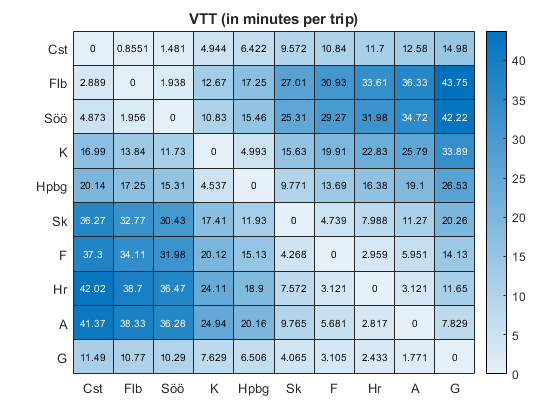

% Heat map X->Y and Z is the VTT in terms of travel time
plot_figure("time-trip",line,delta_R_time)

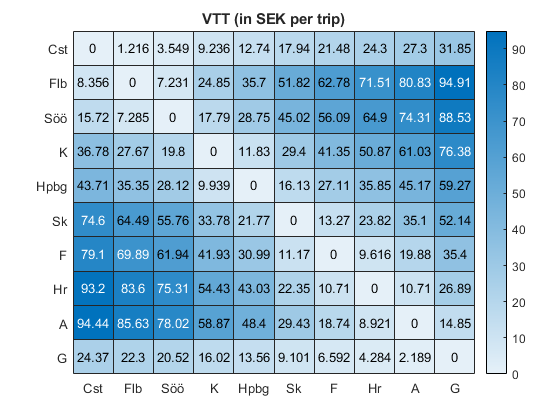

% In terms of costs/trip
plot_figure("cost-trip",line,delta_R_cost)

## Sensitivity analyses

### >  VTT calculation - delays (length and probability)

delay_prob_param = 0.001:.1:2;
delay_param = 0.001:.1:2;
agg_R_time_avg_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
agg_R_cost_avg_prob = zeros(size(delay_prob_param,2),size(delay_param,2));
for p=1:size(delay_param,2)
    for i=1:size(delay_prob_param,2)
        [line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob, ~] = read_input('./1_scenario/data_intercity.xlsx', 'intercity', delay_param(p), delay_prob_param(i));
        % assess the value of train traffic information in terms of accessibility
        delta_R_time = assess_vtt("time", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob);
        % assess the value of train traffic information in terms of social costs
        delta_R_cost = assess_vtt("cost", line, travel_time, alt_travel_time, waiting_time, avg_delay, delay_prob);
        % Non-weighted average
        agg_R_time_avg_prob(i,p) = aggregate_vtt("avg", delta_R_time, []);
        agg_R_cost_avg_prob(i,p) = aggregate_vtt("avg", delta_R_cost, []);
    end
end

### > Plots

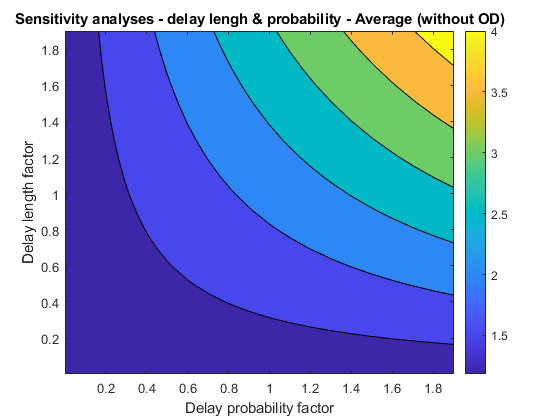

% Plot the results as contours
figure;
contourf(delay_prob_param, delay_param, agg_R_cost_avg_prob./agg_R_time_avg_prob);
colorbar;
xlabel('Delay probability factor');
ylabel('Delay length factor');
title('Sensitivity analyses - delay lengh & probability - Average (without OD)');